close all
clc
clear

## Import data

X1 = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\光谱数据\氙灯反射.xlsx', 'X'); %X1:Reflectance Spectra
X2 = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\光谱数据\氙灯透射.xlsx', 'X'); %X2:Transmittance Spectra
Y = xlsread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\20240618番茄红素颜色融合实验\理化数据.xlsx', 'LYC');         %Y :Predicted quality index
Z = xlsread('D:\2ZYHfiles\实验数据汇总\实验数据汇总-按照时间和内容排序\20240531番茄红素颜色融合预实验\理化数据.xlsx', 'Z'); %Z :Spectra wavelength

## Preprocessing and spectra combination

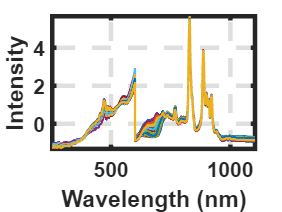

%Combination of transmittance and reflectance spectra
start_column1 = 100;
end_column1 = 846;
selected_columns1 = start_column1:end_column1;

start_column2 = 847;
end_column2 = 2000;
selected_columns2 = start_column2:end_column2;

X1tmp = X1(:, selected_columns1);
Z1tmp = Z(start_column1:end_column1);
X2tmp = X2(:, selected_columns2);
Z2tmp = Z(start_column2:end_column2);

X1tmp=snv(X1tmp);
X2tmp=snv(X2tmp);

X = [X1tmp, X2tmp];
Z = [Z1tmp; Z2tmp];


figure
ROW=size(X,1);
for i = 1:ROW
    plot(Z,X(i,:), 'LineWidth', 1.5)
    %plot(Z,X1(i,:), 'LineWidth', 1.5,'Color','#4169E1') #Check spectra X1
    %plot(Z,X2(i,:), 'LineWidth', 1.5,'Color','#FF6347') #Check spectra X2
    hold on
end
IntensityFigure();
hold off

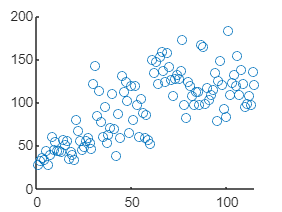


figure
scatter(1:length(Y), Y);

## Spectra sorted in descending order by the Y value

SD=std(Y, 1);
[row,col]=size(X);
Data=[Y X];
Data=sortrows(Data,-1);
Y=Data(:,1);
X=Data(:,2:(col+1));
X_raw=X;
Y_raw=Y;
Z_raw=Z;

## Model development using PLS

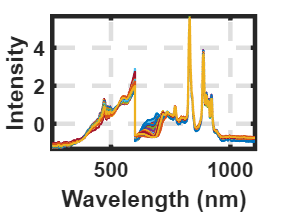

figure
for i = 1:ROW
    plot(Z,X(i,:), 'LineWidth', 1.5)
    hold on
end
IntensityFigure();
hold off

FinalResult=[];
num=0;
cnt = 0;

while cnt<1
        X=X_raw;
        Y=Y_raw;
        
        % Data set division
        %Data_Label=RandomSampleDivision(X,Y);
        Data_Label=descendingorder_extraction(X,Y,1/3);

        X_train = Data_Label.spec_train;
        Y_train = Data_Label.target_train;
        X_pre = Data_Label.spec_test;
        Y_pre = Data_Label.target_test;
        
        %Feature wavelength extraction1 CARS
%         A1=8; fold=10;  method='center'; num=500; selectLV=0; originalVersion=0; order=0;
%         CARS=carspls(X_train,Y_train,A1,fold,method,num,selectLV,originalVersion,order);  % original version of CARS
%         X_train = X_train(:,CARS.vsel);
%         X_pre = X_pre(:,CARS.vsel);
%         Z = Z_raw(CARS.vsel, :);
        
        %Feature wavelength extraction2 RF
        A=8; method='center'; N=500; Q=5; criterion='RegCoef';
        RF=randomfrog_pls(X_train, Y_train,A, method, N, Q, criterion);
        [n]=RF.Vtop10;
        n = sort(n);
        X_train = X_train(:,n);
        X_pre = X_pre(:,n);
        Z = Z_raw(n, :);
        
        %Feature wavelength extraction3 UVE
%           A=10; method='center'; N=100; ratio=2/3;
%           UVE=mcuvepls(X_train, Y_train, A, method, N, ratio);
%           [n]=UVE.SortedVariable(:,1:40);
%           n = sort(n);
%           X_train = X_train(:,n);
%           X_pre = X_pre(:,n);
%           Z = Z_raw(n, :);
        
        %Modeling process
        SDc=std(Data_Label.target_train, 1);
        SDp=std(Data_Label.target_test, 1);
        CV = plscv(X_train,Y_train,8,10);
        PLS=pls(X_train,Y_train,CV.optLV);
        [ypred,Rp2,RMSEP]=plsval(PLS,X_pre,Y_pre,CV.optLV);
        RPD=SDp/RMSEP;
        CPI=3^(Rp2+(RPD-3)/3-abs(RMSEP/PLS.RMSEC-1));
        
        %Modeling results
        ModelingResult=[num,PLS.Rc2,PLS.RMSEC,Rp2,RMSEP,RPD,CPI];
    
        num=num+1;
        FinalResult(num,:)=ModelingResult;

        cnt = cnt+1;
end

The 100th sampling for random frog finished.
The 200th sampling for random frog finished.
The 300th sampling for random frog finished.
The 400th sampling for random frog finished.
The 500th sampling for random frog finished.
历时 1.113902 秒。


The 1th group finished.
The 2th group finished.
The 3th group finished.
The 4th group finished.
The 5th group finished.
The 6th group finished.
The 7th group finished.
The 8th group finished.
The 9th group finished.
The 10th group finished.



FinalResult=sortrows(FinalResult,4,'descend');